# A. Transfer function

Objective:

- Observe a system variables and deduce the input/output

- Write the governing equation

- Transform the equation into frequency domain using Laplace transform

- Observe the step response (open loop response)

What is transfer function?

- An equation that relates the input and output of a system

- Written in frequency domain, not time domain

- Easy to manipulate for a complex system

- Provide information on the stability of a system easily

### 1 - First order system

The order of the system is defined by the highest order or power of the polynomial of the transfer function. Below is an example of an electrical system in first order of an RC circuit.

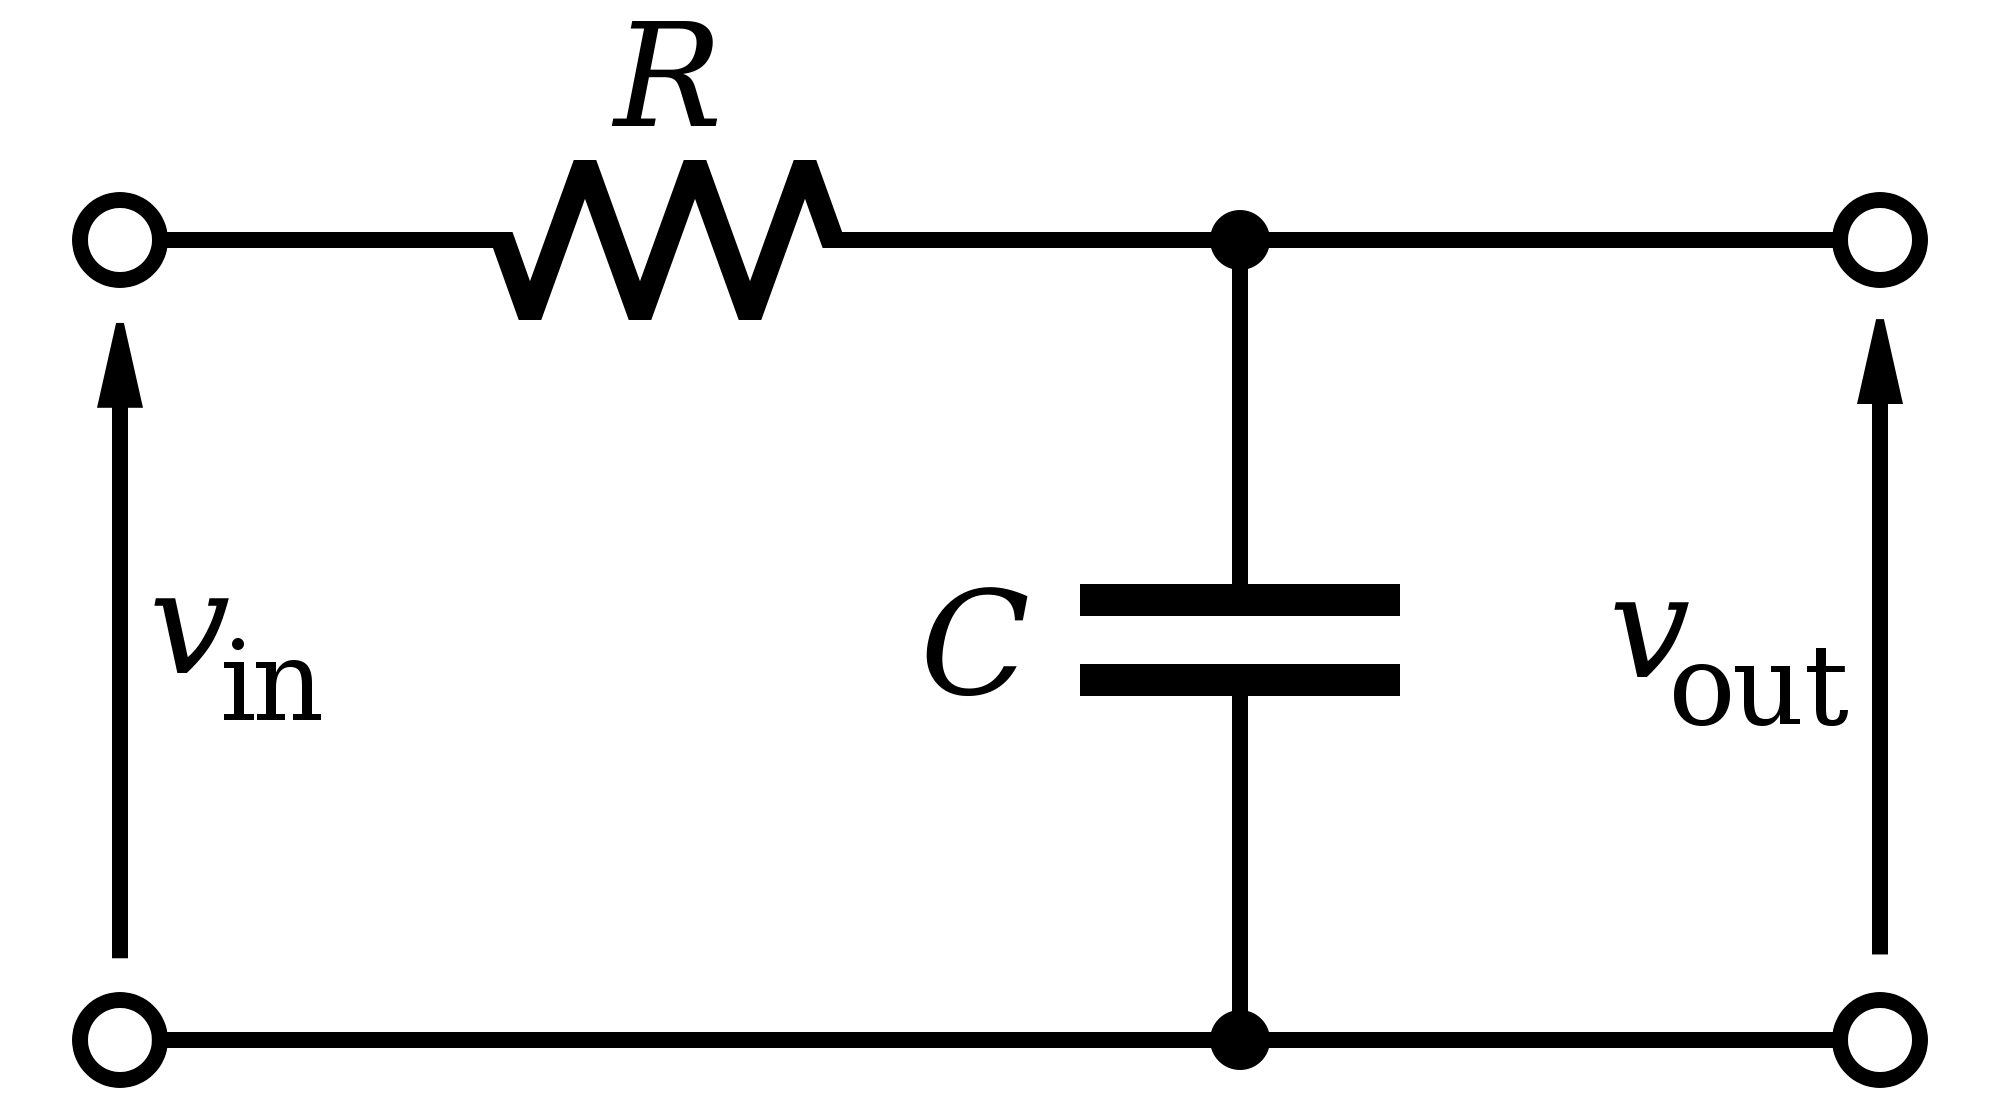

Consider on the left the input voltage and the voltage across the capacitor as output voltage. So, we can write using Kirchoff voltage law:

Using [Laplace transform](https://www.integral-table.com/downloads/LaplaceTable.pdf), we transform the differential equation into frequency domain as:


$$\begin{array}{l}
V_{\mathrm{in}} \left(s\right)=\mathrm{RC}\ldotp s\ldotp V_c \left(s\right)+V_c \left(s\right)\\
\Rightarrow V_{\mathrm{in}} \left(s\right)=V_c \left(s\right)\left\lbrack \mathrm{RC}\ldotp s+1\right\rbrack 
\end{array}$$


Therefore, putting it in the form of transfer function:


$$\frac{V_c \left(s\right)}{V_{\mathrm{in}} \left(s\right)}=\frac{1}{\mathrm{RC}\ldotp s+1}$$


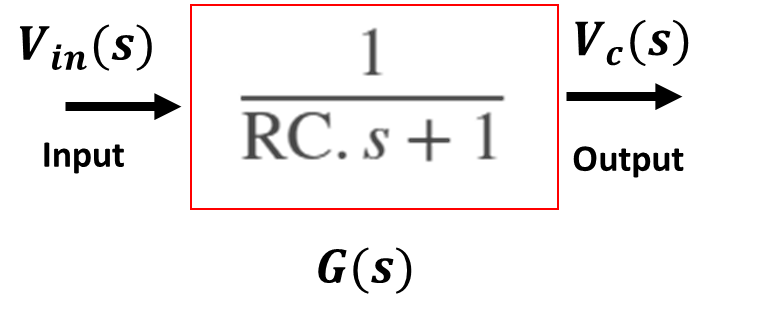

We can define the transfer function G(s) in Matlab by:

R = 10e3;        % resistance in Ohm
C = 50e-6;          % capacitance in Farad
s = tf('s');
G_RC = 1/(R*C*s + 1)

G_RC =
 
      1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



Remark that the highest power of the polynomial is at the power of one.

The characteristic of a system can evaluated based on its step response (Injecting a step input r(t) to the system and observing the variaton of the output).

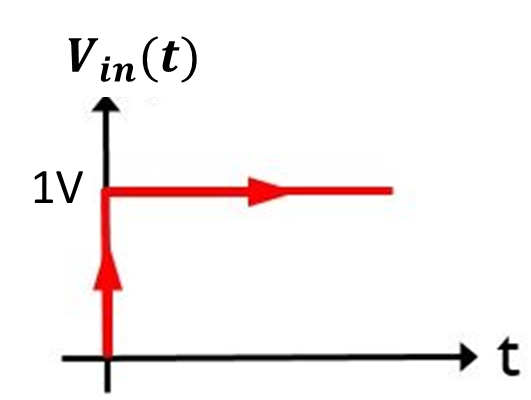

The response of the system is observed by giving a step input of voltage in the caseof RC circuit, a constant input voltage at unity value (1V). The response can be computed by:

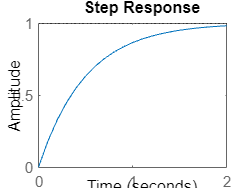

t = 0:0.1:2;
step(G_RC, t)

Observation: Increasing output voltage  as time increases and goes into steady state at 1V, taking close to 2 seconds. This is what we call as step response or open loop response. It characterize the open loop system, without any control intervention.

### 2 - Second order system

Figure below shows the schematic diagram and the FBD on the masss spring system.

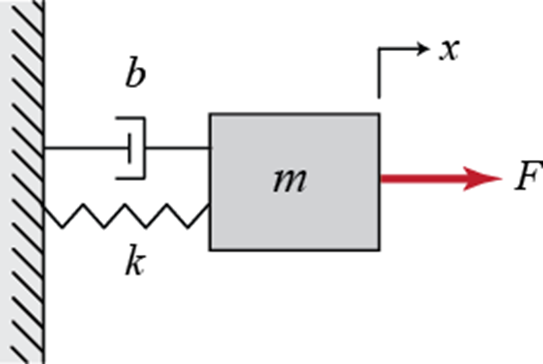        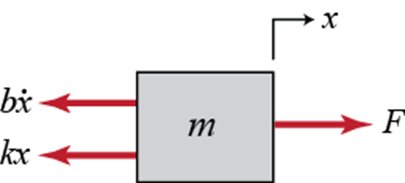

The differential equation form the FBD is:

Using [Laplace transform](https://www.integral-table.com/downloads/LaplaceTable.pdf), we get the equation in frequency domain as:

Therefore, putting it in the form of transfer function:

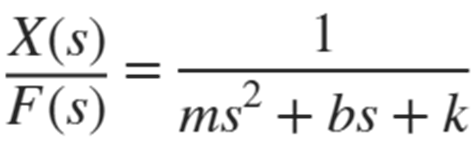

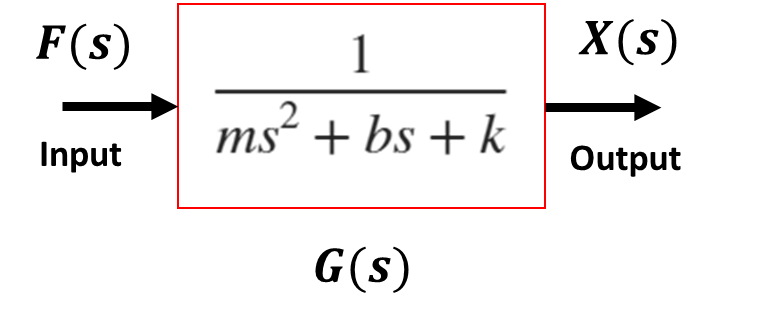

We here define the transfer function in Matlab.

M = 5;         % mass in kg
b = 0.5;        % viscuous friction in N/m/s^2
k = 1;         % spring elasticy in N/m
s = tf('s');
G_MassSpring = 1/(M*s^2 + b*s + k)    

G_MassSpring =
 
          1
  -----------------
  5 s^2 + 0.5 s + 1
 
Continuous-time transfer function.



Remark that the highest power of the polynomial is at the power of two.

This is an open loop transfer function of the mass spring system.The characteristic of a system can evaluated based on its step response (Injecting a step input r(t) to the system and observing the variaton of the output).

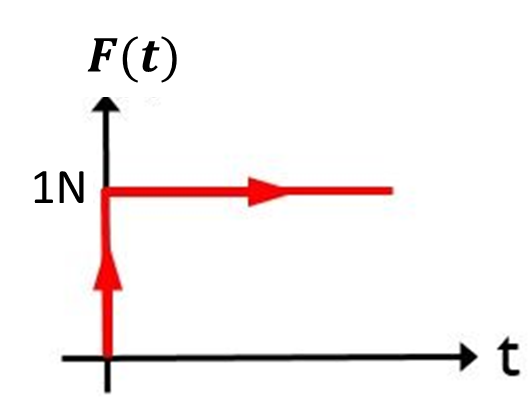

The response of the system is observed by giving a step input of force in the case of mass spring system, a constant input force at unity value (1N). The response can be computed by:

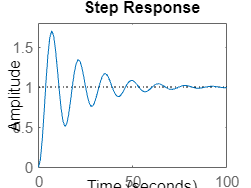

t = 0:100;
step(G_MassSpring, t)

Observation: increasing displacement as the constant force of 1Nm being subjected to the mass spring system. Then, oscillations that settles at around 1m. 

### 3 - Reflections

- What are the difference in temrs of the form of the equation for the first order and second order transfer function?

- By observing the step response of each system (1st order and 2nd order), what are the difference? Oscillations? Steady state?

**Additional remark:** There are other methods to develop a system model:

- The state space : Matrix connecting the variables input and output

- Experimental data identification

For state space in Matlab, we can convert the transfer function to state space by the following command.

ss_RC = ss(G_RC)

ss_RC =
 
  A = 
       x1
   x1  -2
 
  B = 
       u1
   x1   2
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



ss_MassSpring = ss(G_MassSpring)

ss_MassSpring =
 
  A = 
         x1    x2
   x1  -0.1  -0.4
   x2   0.5     0
 
  B = 
        u1
   x1  0.5
   x2    0
 
  C = 
        x1   x2
   y1    0  0.8
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



## Reference 

[1]    Norman S. Nise, “CONTROL SYSTEMS ENGINEERING Eighth Edition,” UMP** Repository**, accessed September 21, 2023, https://repository.gctu.edu.gh/items/show/477.

[2] *DC Motor Position: System Modeling*. Control Tutorials for MATLAB and Simulink - Motor Position: System Modeling. (n.d.). https://ctms.engin.umich.edu/CTMS/index.php?example=MotorPosition&section=SystemModeling 